clear all 
clc

kuka = loadrobot('kukaIiwa14');
kuka.DataFormat = 'column';

dt = 0.005;
num_snaps = 1000;
num_traj = 100;
t_span = 0:dt:dt*num_snaps;

%% Initialize the values
% X(1:7,1) = (pi/2)*(2*rand(7,1) - 1); %joint angles
% X(8:14,1) = 0.1*(2*rand(7,1) - 1); %joint velocity
% tf = getTransform(kuka,X(1:7,1),'iiwa_link_ee');
% X_end(:,1) = tf(1:3,4);
% for i = 1:num_snaps
%     tau(:,i) = 0.1*(2*rand(1,7) - 1); %input torques
% 
%     th_ddot = forwardDynamics(kuka,X(1:7,i),X(8:14,i),tau(:,i));
% 
%     X(8:14,i+1) = th_ddot*dt + X(8:14,i);
%     X(1:7,i+1) = th_ddot*dt + X(1:7,i);
% 
%     tf = getTransform(kuka,X(1:7,i+1),'iiwa_link_ee');
%     X_end(:,i+1) = tf(1:3,4);
% 
% end

% for i = 1:(num_snaps)/10
%     wp(:,i) = kuka.randomConfiguration;
% end
% 
% t_wp = linspace(0,dt*num_snaps,size(wp,2));
% 
% [X(1:7,:),X(8:14,:), th_ddot] =  minjerkpolytraj(wp, t_wp, num_snaps);
% 
% 
% for i = 1:num_snaps
%     tau(:,i) = inverseDynamics(kuka,X(1:7,i),X(8:14,i),th_ddot(:,i));
% 
%     tf = getTransform(kuka,X(1:7,i),'iiwa_link_ee');
%     X_end(:,i) = tf(1:3,4);
% 
% end

%% 3D
% for i = 1:num_traj
%     % Initialize the values
%     X(i,1,1:7) = (pi/2)*(2*rand(7,1) - 1); %joint angles
%     X(i,1,8:14) = 0.1*(2*rand(7,1) - 1); %joint velocity
%     tf = getTransform(kuka,reshape(X(i,1,1:7),[7,1]),'iiwa_link_ee');
%     X_end(i,1,:) = tf(1:3,4);
%     for j = 1:num_snaps
%         th_ddot = (2*pi/3)*(2*rand(7,1) - 1);
%         tau(i,j,:) = inverseDynamics(kuka,reshape(X(i,j,1:7),[7,1]),reshape(X(i,j,8:14),[7,1]),th_ddot);
%     
%         X(i,j+1,8:14) = reshape(th_ddot,[1,1,7])*dt + X(i,j,8:14);
%         X(i,j+1,1:7) = X(i,j,8:14)*dt + X(i,j,1:7);
%     
%         tf = getTransform(kuka,reshape(X(i,j+1,1:7),[7,1]),'iiwa_link_ee');
%         X_end(i,j+1,:) = tf(1:3,4);
%     
%     end
% end

%% 2D
% for i = 1:num_traj
%     ul_joints = [0;1;0;1;0;1;0];
%     l_joints= [-0.0;-1;0.0;-1.65;-0.0;-1.3;0.0];
%     % Initialize the values
%     X(i,1,1:7) = (pi/2)*(2*rand(7,1) - 1).*ul_joints + l_joints; %joint angles
%     X(i,1,8:14) = 0.1*(2*rand(7,1) - 1).*ul_joints; %joint velocity
%     tf = getTransform(kuka,reshape(X(i,1,1:7),[7,1]),'iiwa_link_ee');
%     X_end(i,1,:) = tf(1:3,4);
%     for j = 1:num_snaps
%         th_ddot = (pi/4)*(2*rand(7,1) - 1).*ul_joints;
%         tau(i,j,:) = inverseDynamics(kuka,reshape(X(i,j,1:7),[7,1]),reshape(X(i,j,8:14),[7,1]),th_ddot);
%     
%         X(i,j+1,8:14) = reshape(th_ddot,[1,1,7])*dt + X(i,j,8:14);
%         X(i,j+1,1:7) = X(i,j,8:14)*dt + X(i,j,1:7);
%     
%         tf = getTransform(kuka,reshape(X(i,j+1,1:7),[7,1]),'iiwa_link_ee');
%         X_end(i,j+1,:) = tf(1:3,4);
%     
%     end

% for i = 1:num_traj
%     ul_joints = [0;1;0;1;0;1;0];
%     l_joints= [-0.0;-1;0.0;-1.65;-0.0;-1.3;0.0];
%     % Initialize the values
%     X(i,1,1:7) = (pi/2)*(2*rand(7,1) - 1).*ul_joints + l_joints; %joint angles
%     X(i,1,8:14) = 0.1*(2*rand(7,1) - 1).*ul_joints; %joint velocity
%     tf = getTransform(kuka,reshape(X(i,1,1:7),[7,1]),'iiwa_link_ee');
%     X_end(i,1,:) = tf(1:3,4);
%     for j = 1:num_snaps
%         tau(i,j,:) = (2*rand(7,1) - 1).*ul_joints;
%         th_ddot = forwardDynamics(kuka,reshape(X(i,j,1:7),[7,1]),reshape(X(i,j,8:14),[7,1]),reshape(tau(i,j,:),[7,1]));
%     
%         X(i,j+1,8:14) = reshape(th_ddot,[1,1,7])*dt + X(i,j,8:14);
%         X(i,j+1,1:7) = X(i,j,8:14)*dt + X(i,j,1:7);
%     
%         tf = getTransform(kuka,reshape(X(i,j+1,1:7),[7,1]),'iiwa_link_ee');
%         X_end(i,j+1,:) = tf(1:3,4);
%     
%     end
% end

% input are sines
for i = 1:num_traj
    ul_joints = [0;1;0;1;0;1;0];
    tau_joints = [0;1;0;1;0;0.1;0];
    l_joints= [-0.0;-1;0.0;-1.65;-0.0;-1.3;0.0];
    % Initialize the values
    X(i,1,1:7) = (pi/2)*(2*rand(7,1) - 1).*ul_joints + l_joints; %joint angles
    X(i,1,8:14) = 0.1*(2*rand(7,1) - 1).*ul_joints; %joint velocity
    tf = getTransform(kuka,reshape(X(i,1,1:7),[7,1]),'iiwa_link_ee');
    X_end(i,1,:) = tf(1:3,4);
    phase = pi*(2*rand(7,1) - 1);
    amp = (2*rand(7,1) - 1);
    freq = 5*rand(7,1);
    for j = 1:num_snaps
        tau(i,j,:) = amp.*sin(freq*pi*(j/num_snaps) + phase).*tau_joints;
        th_ddot = forwardDynamics(kuka,reshape(X(i,j,1:7),[7,1]),reshape(X(i,j,8:14),[7,1]),reshape(tau(i,j,:),[7,1]));
    
        X(i,j+1,8:14) = reshape(th_ddot,[1,1,7])*dt + X(i,j,8:14);
        X(i,j+1,1:7) = X(i,j,8:14)*dt + X(i,j,1:7);
    
        tf = getTransform(kuka,reshape(X(i,j+1,1:7),[7,1]),'iiwa_link_ee');
        X_end(i,j+1,:) = tf(1:3,4);
    
    end
end


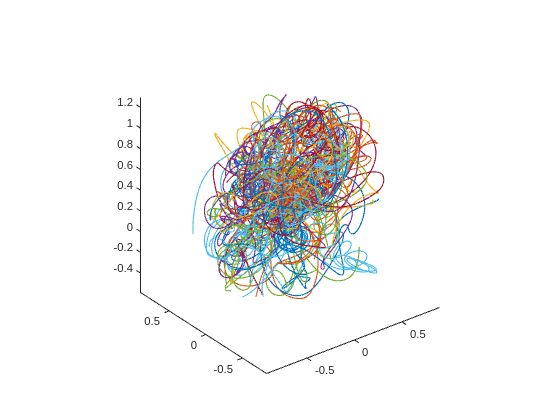

figure()
for i = 1:num_traj
    plot3(X_end(i,:,1),X_end(i,:,2),X_end(i,:,3), 'LineWidth',1)
    hold on
end
axis('equal')

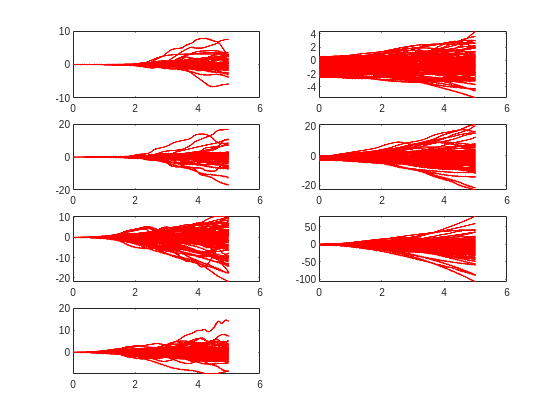

figure()
for i = 1:7
    subplot(4,2,i)
    xlabel('t')
    ylabel(strcat('th',num2str(i)))
    for j = 1:num_traj
        plot(t_span,X(j,:,i), 'r','LineWidth',1.5)
        hold on

    end
end

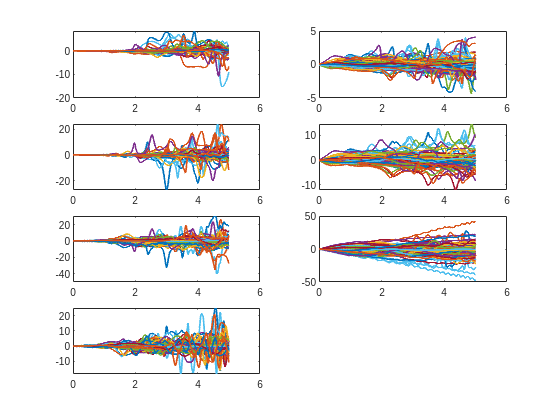

figure()
for i = 1:7
    subplot(4,2,i)
    xlabel('t')
    ylabel(strcat('th dot ',num2str(i)))
    for j = 1:num_traj
        plot(t_span,X(j,:,i+7),'LineWidth',1.5)
        hold on

    end
end

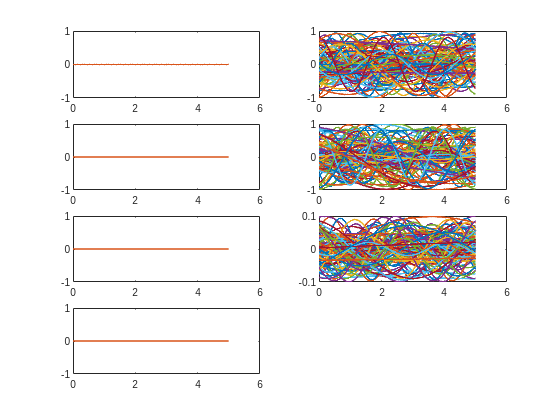

figure()
for i = 1:7
    subplot(4,2,i)
    xlabel('t')
    ylabel(strcat('tau',num2str(i)))
    for j = 1:num_traj
        plot(t_span(1:end-1),tau(j,:,i),'LineWidth',1.5)
        hold on

    end
end

% tau_red = tau(:,:,[2,4,6]);

% save("dynamics\Dataset_MATLAB\X.mat","X")
% save("dynamics\Dataset_MATLAB\X_end.mat","X_end")
% save("dynamics\Dataset_MATLAB\U.mat","tau")


save("Dataset_MATLAB/2D/data.mat","X_end","X","tau",'dt','num_snaps',"num_traj")
% save("dynamics\Dataset_MATLAB\X_end.mat","X_end")
% save("dynamics\Dataset_MATLAB\U.mat","tau")



% close all
% skip = 5;
% 
% figure()
% set(gcf, 'Visible', 'on');
% 
% for i = 1:(num_snaps/skip)
%     show(kuka,X(1:7,skip*i), 'Frames','off', 'PreservePlot', false);
%     hold on
%     plot3(X_end(1,1:skip*i),X_end(2,1:skip*i),X_end(3,1:skip*i), 'LineWidth',3)
%     drawnow
% end